# **Trace Contours** · Getting started

For more help, type:

doc trace_contours

If you use this toolbox, please cite: [Camouflage Detection & Signal Discrimination: Theory, Methods & Experiments](http://dx.doi.org/10.13140/RG.2.2.10585.80487).

Bugs/questions/comments to abhranil.das@utexas.edu.

Abhranil Das, Center for Perceptual Systems, University of Texas at Austin

### Read an image and detect edges:

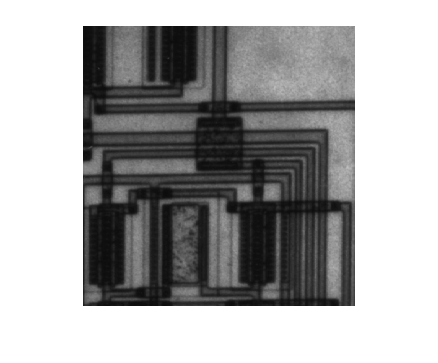

img=imread('circuit.tif');
imshow(img)

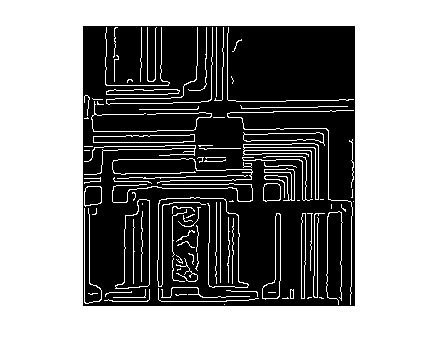

edge_pixels=edge(img,'Canny');
imshow(edge_pixels)

### Trace edge contours:

contours=trace_contours(edge_pixels)

contours = 218×1 cell array
    { 11×2 double}
    {140×2 double}
    { 12×2 double}
    {  2×2 double}
    { 30×2 double}
    {  2×2 double}
    { 20×2 double}
    { 25×2 double}
    { 19×2 double}
    {117×2 double}
    { 40×2 double}
    { 34×2 double}
    { 10×2 double}
    { 16×2 double}
    { 19×2 double}
    { 24×2 double}


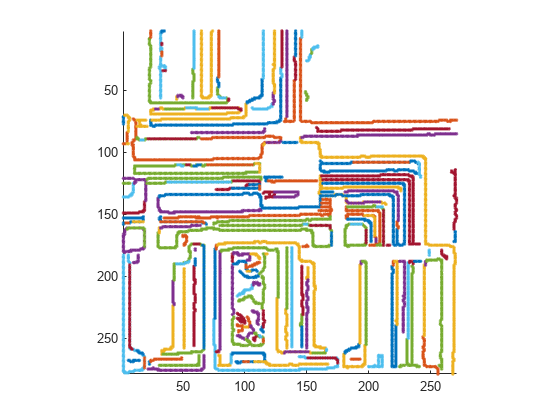

figure; hold on

for i=1:length(contours)
    contour=contours{i};
    plot(contour(:,2),contour(:,1),'.')
end
axis image
set(gca,'YDir','reverse')